clc;clear;close all;

## 轨迹NURBS曲线插补

track = load('track.txt'); % 位置
xforplot = track(:,1);
yforplot = track(:,2);
zforplot = track(:,3);
track = track(round(linspace(1,numrows(track),8)),1:3);%linspace函数用于生成一个包含8个等间距元素的向量，这些元素的值介于1和numrows(track)之间（四舍五入取整）。
% 然后，track变量被创建为具有3列的矩阵，其中每一列都包含上面生成的向量的相应元素。
pose = load('rotvect.txt'); % 姿态
pose = pose(round(linspace(1,numrows(pose),8)),1:3);
D_X = track(:,1); D_Y = track(:,2); D_Z = track(:,3);  % TCP 坐标
R_X = pose(:,1); R_Y = pose(:,2); R_Z = pose(:,3);  % 旋转向量
[m,n] = size([track,pose]);% m行n列

% step1  计算四元数
Q = []; % 用来储存四元数
for i = 1:m
    q = rotvec2quaternion(R_X(i), R_Y(i), R_Z(i));
    Q = [Q;q];%每一行q0, q1, q2, q3
end
% step2 根据数据点，反算出位置控制点
[P_X,P_Y,P_Z,U,w] = counter_B(D_X,D_Y,D_Z);  %节点矢量个数为m+2*k,应为14个  ?

## 轨迹NURBS插补&姿态Squad插补

straj=[];
k=1; %生成位姿的行数
Sn = GetCtlPoints(Q,m);%求姿态的控制点

for i=1:m-1 %pose中的行
    t=0;
    N = ComDisPntsNum(D_X, D_Y, D_Z, i); %插值点数
    t_ = 1/N;
    for j=1:N %两行pose之间插n个点
        Pra = ((1 - t)* w(i) + t* w(i+1)) + 1.0e-6;
        [straj(k,1),straj(k,2),straj(k,3)] = Bspline(P_X,P_Y,P_Z,U,Pra); %NURBS
%         straj(k,4:7) = slerp(Q(i,1:4),Q(i+1,1:4),t);
        straj(k,4:7) = Squad(Q(i,:),Sn(i,:),Q(i+1,:),Sn(i+1,:),t); %Squad
        straj(k,4:6) = quaternion2rpy(straj(k,4:7));
        straj(k,4:6) = rpy2rotvec(straj(k,4),straj(k,5),straj(k,6));
        k = k+1; 
        t = t + t_;
    end    
end

straj(:,7)=[];

## 画图

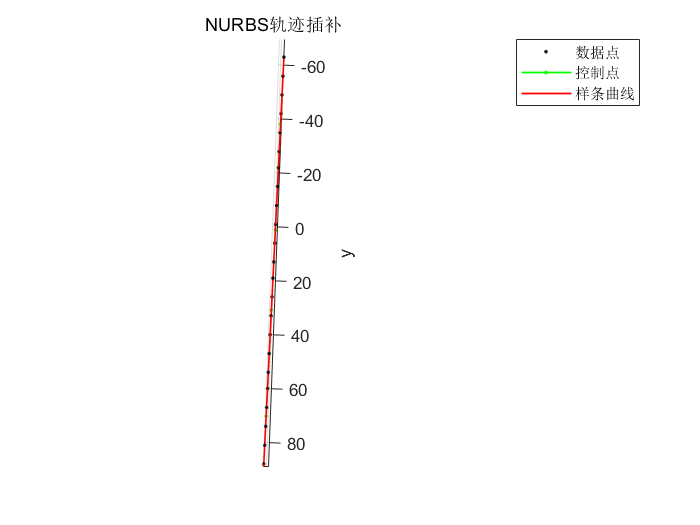

% 导出straj
% writematrix(straj,'straj.txt');
% 数据点
% plot3(D_X,D_Y,D_Z,'.k','LineWidth',4);
plot3(xforplot,yforplot,zforplot,'.k','LineWidth',4);
hold on 
% 控制点
plot3(P_X,P_Y,P_Z,'.g-','LineWidth',1);
hold on
% 样条曲线
plot3(straj(:,1),straj(:,2),straj(:,3),'r','LineWidth',1); %输出末端轨迹
hold off
xlabel('x')
ylabel('y')
zlabel('z')
title('NURBS轨迹插补');
legend('数据点','控制点','样条曲线')
% legend('数据点','样条曲线')
axis equal